clear all; close all;
syms x1(t)
syms x2(t)
x = sym('x',[1 2]);
syms c g m l 


%================================>>>USER_INPUTS<<<============================
%system42_syms = [   -x1+x2+x1^3; -x1]
%system42_syms = [x2;  -0.5*x2 - 0.6*x1 - (-0.7)*(x1.^3)]
%Test compare to prev
system42_syms = [ x2; -(c/m)*x2 - (g/l)*sin(x1)]

$$system42\_syms(t) = \left(\begin{array}{c} x_{2}\left(t\right)\\ -\frac{c\,x_{2}\left(t\right)}{m}-\frac{g\,\sin\left(x_{1}\left(t\right)\right)}{l} \end{array}\right)$$


%Lapunov| V(0) = 0, V > 0 w otoczeniu (0, 0), Vprim <= 0 trzeba sprawdzić gdzie jest,  
V = (m*g*l)*(1-cos(x1)) + 0.5*(m * l^2)*x2^2

$$V(t) = \frac{l^{2}\,m\,{x_{2}\left(t\right)}^{2}}{2}-g\,l\,m\,\left(\cos\left(x_{1}\left(t\right)\right)-1\right)$$

%V = 0.5*(x1^2 + x2^2)

%Lassale| krzywa V-L musi na Vprim < 0 i to jest na pewno obszar
%przyciągania


%X0
x0 = [-pi/4, 0];

% FUNNY math on analityc
system42_sym_pureX = subs(system42_syms, [x1, x2], x)

$$system42\_sym\_pureX(t) = \left(\begin{array}{c} x_{2}\\ -\frac{c\,x_{2}}{m}-\frac{g\,\sin\left(x_{1}\right)}{l} \end{array}\right)$$

V_pureX = subs(V, [x1, x2], x)

$$V\_pureX(t) = \frac{l^{2}\,m\,{x_{2}}^{2}}{2}-g\,l\,m\,\left(\cos\left(x_{1}\right)-1\right)$$

V_prim = diff(V,t)

$$V\_prim(t) = m\,x_{2}\left(t\right)\,l^{2}\,\frac{\partial }{\partial t}x_{2}\left(t\right)+g\,m\,\sin\left(x_{1}\left(t\right)\right)\,l\,\frac{\partial }{\partial t}x_{1}\left(t\right)$$

oldq = [diff(x1(t), t)', diff(x2(t), t)'];
V_prim = subs(V_prim, oldq', system42_syms);
V_prim_pureX = subs(V_prim, [x1, x2], x)

$$V\_prim\_pureX(t) = g\,l\,m\,x_{2}\,\sin\left(x_{1}\right)-l^{2}\,m\,x_{2}\,\left(\frac{c\,x_{2}}{m}+\frac{g\,\sin\left(x_{1}\right)}{l}\right)$$

%------------------------------------------->>>MATLAB CANT SOLVE ANALYTIC
%BOUNARY LINE <<<-------------------------------------

%matlab functions
system42_mf = matlabFunction(subs(system42_syms, [x1, x2], x));
V_mf = matlabFunction(subs(V, [x1, x2], x));
V_prim_mf = matlabFunction(subs(V_prim, [x1, x2], x));

%wrappers
system42 = @(t, x) system42_mf(t, x(1), x(2));
V_fun = @(x1, x2) V_mf(0, x1, x2);
V_prim_fun = @(x1, x2) V_prim_mf(0, x1, x2);

l = 1;

### Trajektorie stanu na warunki początkowe

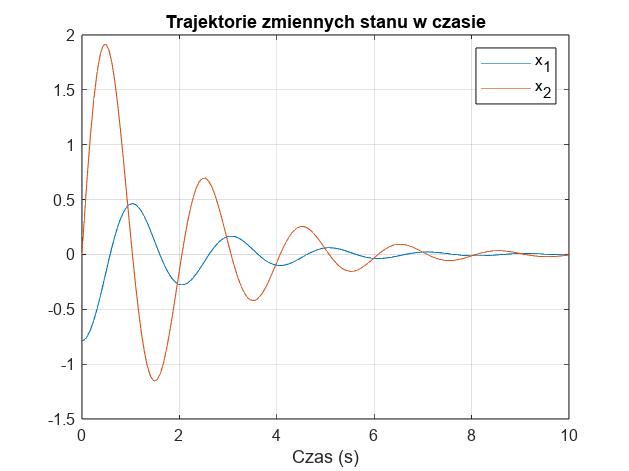

%Simulation
tmax = 100;

[t_resp, x_resp] = ode45(@(t,x) system42(t,x),[0 tmax],x0');
figure;
plot(t_resp, x_resp(:,1), t_resp, x_resp(:,2)), xlim([0 10]),
xlabel('Czas (s)'), legend('x_1','x_2'), grid on
title("Trajektorie zmiennych stanu w czasie")

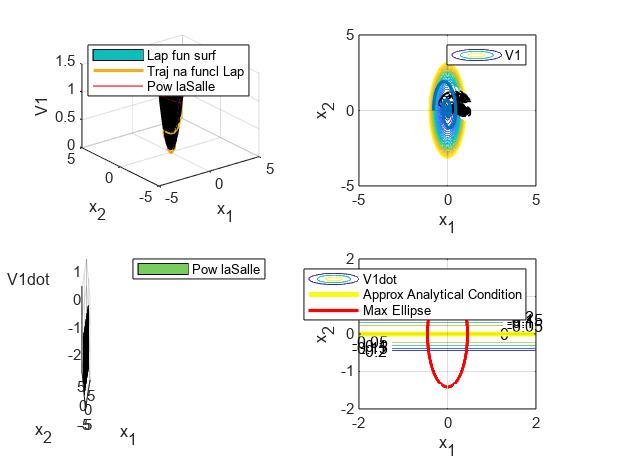

%calculate lasalle bound
lasalle_bound = solve(subs(V - l, [x1, x2], [x(1), x(2)]), x(1));
lasalle_bound_fun = matlabFunction(lasalle_bound);
x2_num = -5:0.001:5;
x1_num = lasalle_bound_fun(x2_num);
x1_num(x1_num~=real(x1_num)) = NaN;

% Analyze Lyapunov Functional and its derivative
% Set up a meshgrid
x1_ax = [-5:0.1:5];
x2_ax = [-5:0.1:5];
[X1,X2] = meshgrid(x1_ax,x2_ax);

figure;
subplot(2,2,1)
% Visualize Lyapunov functional as a surface
% Calcute functional over mesh
V1 = V_fun(X1, X2);
% Calculate functional for trajectory
V1_resp = V_fun(x_resp(:, 1), x_resp(:, 2));
lapunov_surf = surf(X1, X2, V1); hold all
% Visualize Lyapunov functional with value L
lasale_plain = plot3(x1_num,x2_num,l*ones(length(x1_num),1),'r');
% Visualize value of Lyapunov functional along the example of trajectory 
trajectory_Lap = plot3(x_resp(:,1),x_resp(:,2),V1_resp,'LineWidth',2);
legend([lapunov_surf; trajectory_Lap; lasale_plain], ["Lap fun surf"; "Traj na funcl Lap"; "Pow laSalle"], 'Location','northeast');
xlabel('x_1')
ylabel('x_2')
zlabel('V1')
zlim([0 1.5]);

subplot(2,2,2)
% Visualize Lyapunov functional as a contour
[C,h] = contour(X1, X2, V1, [-5:0.2:5]);
clabel(C,h);
xlabel('x_1'), ylabel('x_2'), grid on, hold all
% Display trajectory traversing contours
plot(x_resp(:,1),x_resp(:,2),'LineWidth',2)
legend('V1')

subplot(2,2,3)
% Visualize derivative of Lyapunov functional along trajectories as surface
% Calcute derivative of Lyapunov functional over mesh
V1dot = V_prim_fun(X1, X2);
% Calculate derivative of Lyapunov functional for trajectory
lap_der_surf = surf(X1, X2, V1dot);
xlabel('x_1'), ylabel('x_2'), zlabel('V1dot')
zlim([-2, 1])
legend(lap_der_surf, "Pow laSalle");

subplot(2,2,4)
% Visualize derivative of Lyapunov functional along trajectories as contour
[C,h] = contour(X1, X2, V1dot,[-0.2:0.05:0.2]);
clabel(C,h), hold all;
% Visualize approx analytical condition
contour(X1, X2, V1dot, [0,0], 'LineWidth', 3)


% Visualize ellipse
plot(x1_num,x2_num,'r','LineWidth',2)

xlim([-2 2]), ylim([-2 2]);
xlabel('x_1'), ylabel('x_2'), grid on
legend('V1dot','Approx Analytical Condition','Max Ellipse')

### Trajektoria stanu na funkcjonale Lapunowa

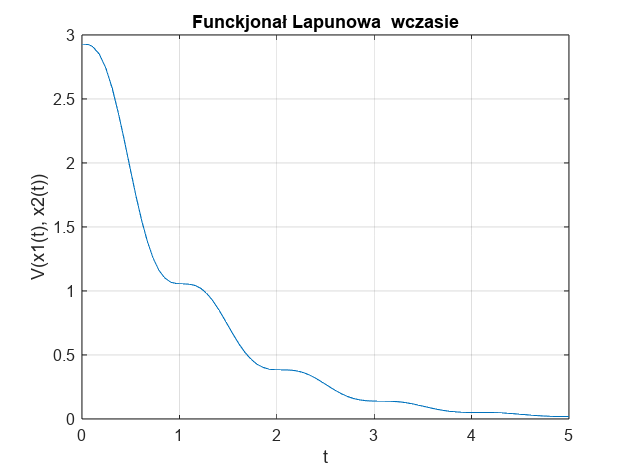

figure
plot(t_resp, V1_resp)
xlim([0, 5]);
xlabel('t'), ylabel('V(x1(t), x2(t))'), grid on
title("Funckjonał Lapunowa  wczasie");

### Trajektoria stanu na pochodnej funkcjonału Lapunowa

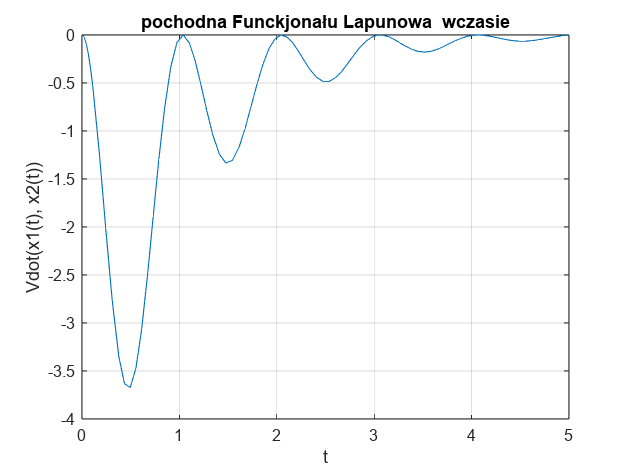

figure
plot(t_resp, V_prim_fun(x_resp(:,1),x_resp(:,2)))
xlim([0, 5]);
xlabel('t'), ylabel('Vdot(x1(t), x2(t))'), grid on
title("pochodna Funckjonału Lapunowa  wczasie");

### Portret fazowy i sprawdzenie lasalle'a

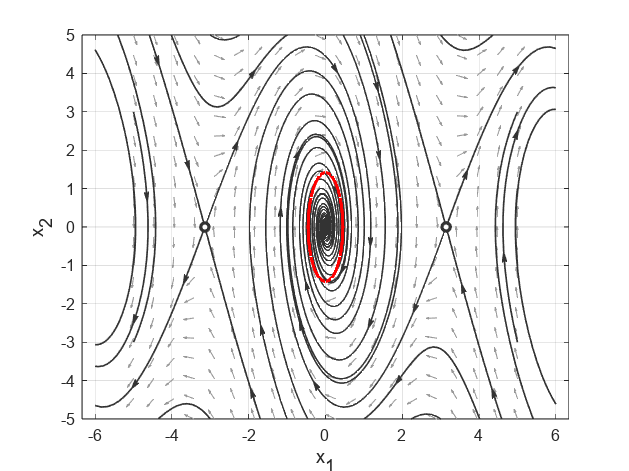

%Phase Portrait
figure
plotpp(@(t,x) system42(t,x), xlim = [-5, 5], ylim = [-5, 5]), hold all
xlabel('x_1'), ylabel('x_2')
xlim([-5 5]), ylim([-5 5])
axis equal

%Plot ellipse as function of L
plot(x1_num, x2_num,'r', 'LineWidth', 2);

### Linearyzacja

system42_sym_jac = jacobian(system42_sym_pureX, x)

$$system42\_sym\_jac(t) = \left(\begin{array}{cc} 0 & 1\\ -10\,\cos\left(x_{1}\right) & -1 \end{array}\right)$$

Sx_dpos = solve(system42_sym_pureX, x);
[Sx_dpos.x1, Sx_dpos.x2]

$$ans = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$


system42_sym_jac_eq = [];
system42_sym_jac_eq_eig = [];
for n = 1:length(Sx_dpos.x1)
    jac_eq = subs(system42_sym_jac, [x(1), x(2)], [Sx_dpos.x1(n), Sx_dpos.x2(n)]);
    system42_sym_jac_eq(:, :, n) = jac_eq;
    disp("Eigen decomposition")
    [D, V]  = eig(jac_eq)
end

Eigen decomposition


$$D(t) = \left(\begin{array}{cc} -\frac{1}{20}+\frac{\sqrt{39}\,\mathrm{i}}{20} & -\frac{1}{20}-\frac{\sqrt{39}\,\mathrm{i}}{20}\\ 1 & 1 \end{array}\right)$$

$$V(t) = \left(\begin{array}{cc} -\frac{1}{2}-\frac{\sqrt{39}\,\mathrm{i}}{2} & 0\\ 0 & -\frac{1}{2}+\frac{\sqrt{39}\,\mathrm{i}}{2} \end{array}\right)$$

system42_sym_jac_eq

system42_sym_jac_eq =      0     1
   -10    -1


### Portret fazowy i eksperymentalny obszar przyciągania

xlim = [-5, 5];
ylim = [-5, 5];
sens = 0.1;
tspan = linspace(0, 10, 100);

x1_eq = Sx_dpos.x1;
x2_eq = Sx_dpos.x2;

odefun = system42;
plotpp(odefun, xlim = xlim, ylim = ylim)
hold on
x_ = [];
y_ = [];

liczpetle = false %<=============================================

liczpetle = logical
   0


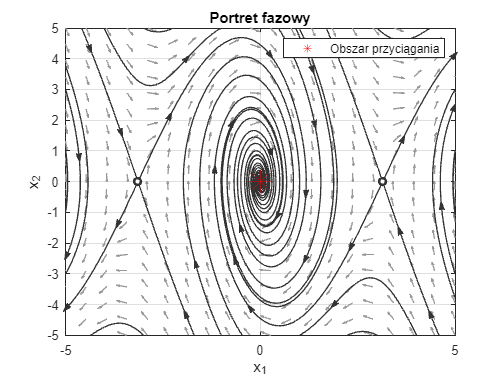

if(liczpetle)
    warning('off', 'all')
    for x_1 = xlim(1):sens:xlim(2)
        for x_2 = ylim(1):sens:ylim(2)
            [t,y] = ode23 (odefun, tspan, [x_1 x_2] );
            for n = 1:numel(x1_eq)
                if abs(y(end,1) - x1_eq(n)) < sens &&...
                        abs(y(end, 2) - x2_eq(n)) < sens 
                    x_(end + 1) = x_1;
                    y_(end + 1)= x_2;
                end %if
            end %for
        end %for
    end %for
    
    arg = [];
    first = [];
    second = [];
    for x_1 = x_
        arg(end + 1) = x_1;
        index = find(x_ == x_1);
        values = y_(index);
        first(end + 1) = min(values);
        second(end + 1) = max(values);
    end
    
    x_ = [arg,sort(arg, 'descend')];
    y_ = [first, flip(second)];
    p = fill (x_ ,y_ ,[0.3010 0.7450 0.9330],'FaceAlpha',0.3);
    p.EdgeColor = [0.3010 0.7450 0.9330];
    plot(0, 0, '.', 'Color', 'red')
    
    legend([p], ["Obszar przyciągania"]);
end %if

sc = scatter(x1_eq, x2_eq, 300 ,"r*");
legend([sc], ["Obszar przyciągania"]);

title("Portret fazowy")
xlabel('x_1'), ylabel('x_2');
hold off

### Porównanie otoczenia punktów równowagi oryuginalnego i zlinearyzowanego

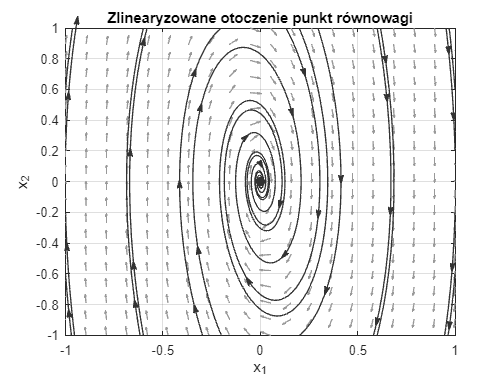

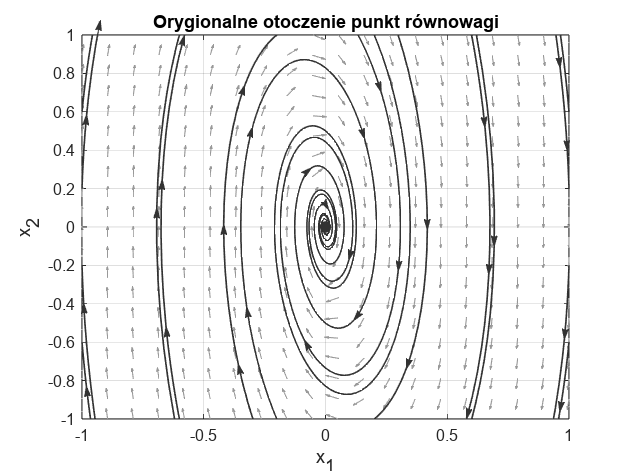

lin_approx_vec = [];

for n = 1:numel(Sx_dpos.x1)
    x1_eq = double(Sx_dpos.x1(n));
    lin_approx = zeros([2, 2]);
    x2_eq = double(Sx_dpos.x2(n));
    x1lim = [x1_eq-1, x1_eq+1];
    x2lim = [x2_eq-1, x2_eq+1];

    if(isreal(x1_eq) && isreal(x2_eq))
    
        lin_approx = double(system42_sym_jac_eq);
        lin_approx = lin_approx(:, :, n);
        lin_approx_vec(:, :, n) = lin_approx;
        
        plotpp(@(t, x) lin_approx * ([x(1); x(2)] - [x1_eq; x2_eq]), xlim = x1lim, ylim = x2lim)
        title("Zlinearyzowane otoczenie punkt równowagi")
        xlabel('x_1'), ylabel('x_2')

        plotpp(system42, xlim = x1lim, ylim = x2lim);
        title("Orygionalne otoczenie punkt równowagi")
        xlabel('x_1'), ylabel('x_2');

    end %if
end

### Porównanie odpowiedzi na warunki początkowe

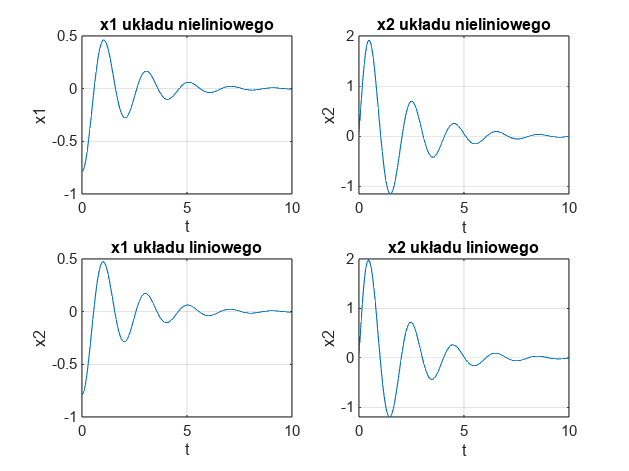

[ t , x ] = ode45 (system42 , [0  10] , x0);
[ t_lin , x_lin ] = ode45 (@( t , x)  lin_approx_vec(:,:, 1) * ([x(1); x(2)] - [x1_eq; x2_eq]) , [ 0  10] , x0);

figure
subplot(2, 2, 1)
plot(t, x(:, 1));
title(["x1 układu nieliniowego"])
xlabel('t'), ylabel('x1');
grid on;
subplot(2, 2, 2)
plot(t, x(:, 2))
title(["x2 układu nieliniowego"])
xlabel('t'), ylabel('x2');
grid on;
subplot(2, 2, 3)
plot(t_lin, x_lin(:, 1));
title(["x1 układu liniowego"])
xlabel('t'), ylabel('x2');
grid on;
subplot(2, 2, 4)
plot(t_lin, x_lin(:, 2))
title(["x2 układu liniowego"])
xlabel('t'), ylabel('x2');
grid on;